## Group 22 - Assignment 1: Beam Analysis

*ME20B051,ME20B052,ME20B052*

### Shear Force Diagram

x1=0:0.5:12;
y11 = 1500 * ones(1, length(x1));
plot(x1,y11,"b");
hold on
xline(12,"--");
x2=12:0.5:24;
y12 = -4500 * ones(1, length(x2));
plot(x2,y12,"b");
hold on
xline(24,"--");
x3=24:0.5:36;
y13 = 3000 * ones(1, length(x3));
plot(x3,y13,"b");
xlabel("Distance (x) in inches");
ylabel("Shear Force in lbf");
title("Shear Force Diagram");
hold off

### Bending Moment Diagram

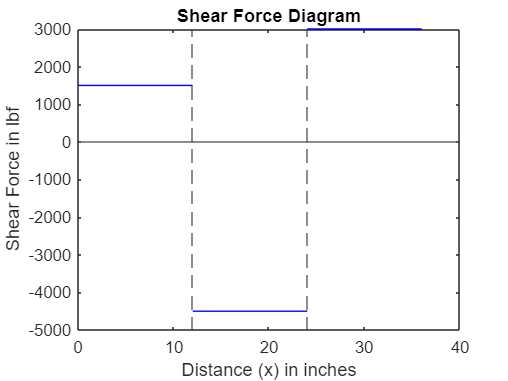

yline(0,"-");

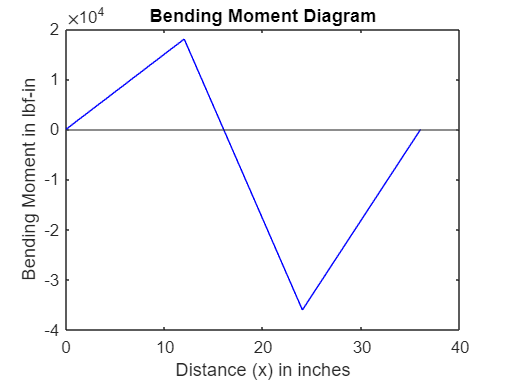

y12= 1500*x1;
plot(x1,y12,"b");
hold on
y22= (72-4.5*x2)*1000;
plot(x2,y22,"b");
hold on
y32= (3*x3-108)*1000;
plot(x3,y32,"b");
xlabel("Distance (x) in inches");
ylabel("Bending Moment in lbf-in");
title("Bending Moment Diagram");
yline(0,"-");
hold off

### Deflection Diagram

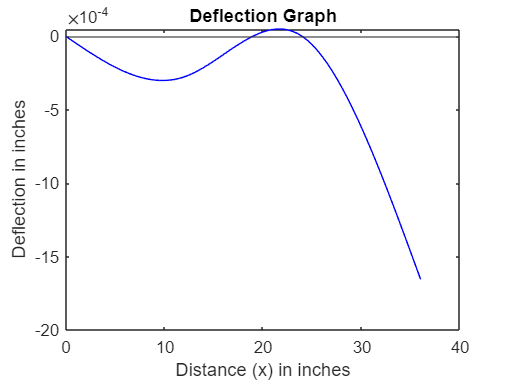

EI=2.901e+7*54;
y13= ((x1.^3/4)-72*x1)*1000/EI;
plot(x1,y13,"b");
hold on
y23= (36*x2.^2-(0.75*x2.^3)-(504*x2)+1728)*1000/EI;
plot(x2,y23,"b");
hold on
y33= (0.5*x3.^3-(54*x3.^2)+1656*x3-15552)*1000/EI;
plot(x3,y33,"b");
xlabel("Distance (x) in inches");
ylabel("Deflection in inches");
title("Deflection Graph");
yline(0,"-");
hold off

### Shear Stress Profile

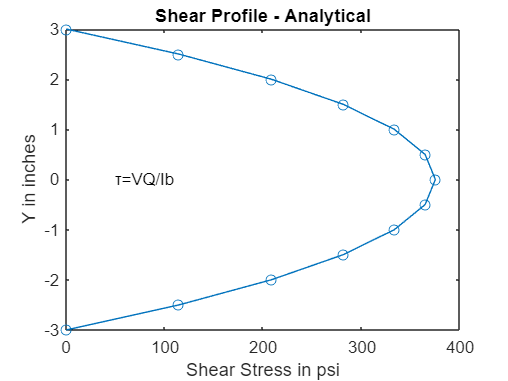

y1=-3:0.5:3;
I=54;
Vmax=4500;
t=(Vmax.*(y1+3).*(3-y1))/(2*I);
plot(t,y1,"-o");
xlabel("Shear Stress in psi");
ylabel("Y in inches");
title("Shear Profile - Analytical");
text ( 50, 0, "τ=VQ/Ib")

### Normal Stress Profile

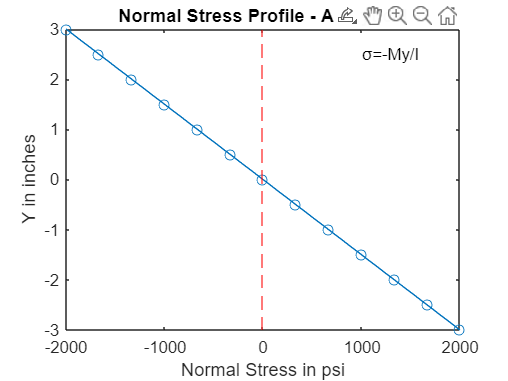

Mmax=36000;
n=-1*Mmax.*y1/I;
plot(n,y1,"-o");
xlabel("Normal Stress in psi");
ylabel("Y in inches");
xline(0,"--r")
title("Normal Stress Profile - Analytical");
text ( 1000, 2.5, "σ=-My/I");